Load the preprocessedImages as feature data

load('preprocessedImagesV2.mat', 'featureData');


%it's an array, start by making category Indices
categoryIndices = featureData(:, 17);

%Set a variable for category names
categoryNames = {'Houndstooth', 'Herringbone', 'Seersucker'};


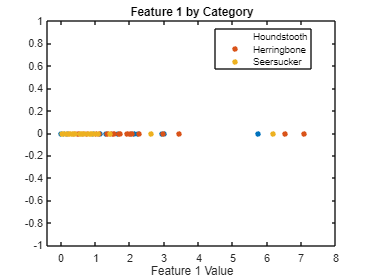

% Example: Visualizing the first feature for each category
% gscatter(featureData(:, 1), zeros(size(featureData, 1), 1), arrayfun(@(x) categoryNames{x}, categoryIndices, 'UniformOutput', false));
% xlabel('Feature 1 Value');
% ylabel(' ');
% legend(categoryNames);
% title('Feature 1 by Category');


% Directly renaming the categories during conversion
featureData(:, 17) = categorical(featureData(:, 17), [1, 2, 3], {'Houndstooth', 'Herringbone', 'Seersucker'});


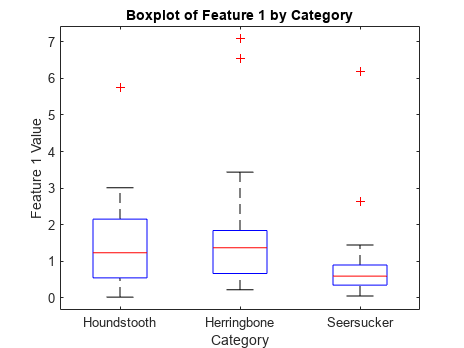

% Convert category indices to category names for each row
categoryLabels = arrayfun(@(x) categoryNames{x}, categoryIndices, 'UniformOutput', false);

% Create the boxplot for the first column, grouped by category labels
boxplot(featureData(:, 1), categoryLabels);

% Optionally, customize the plot
set(gca, 'XTickLabel', categoryNames); % This ensures the category names are shown correctly
title('Boxplot of Feature 1 by Category');
ylabel('Feature 1 Value');
xlabel('Category');

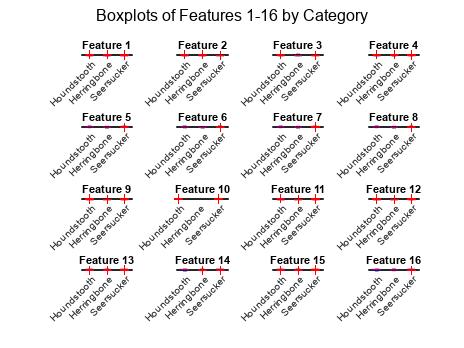

figure; % Create a single figure window
numFeatures = 16; % Total number of features you're interested in
for i = 1:numFeatures
    subplot(4, 4, i); % Arrange the plots in a 4x4 grid
    boxplot(featureData(:, i), categoryLabels, 'Labels', categoryNames);
    title(['Feature ' num2str(i)]);
end
saveas(gcf, ['Feature_' num2str(i) '_Boxplot.png']);
sgtitle('Boxplots of Features 1-16 by Category'); % Super title for the entire figure

  Name              Size            Bytes  Class     Attributes

  featureData      90x17            12240  double              



Dot indexing is not supported for variables of this type.